# Intro to EMG data for Smile vs Frown

#### Neurotechnology, Brains and Machines 2021

#### Analysis by Gati Aher

#### **Revised on April 26, 2021**

Sam Michalka: I collected data while wearing 2 sets of EMG sensors on my face. Sometimes, I smiled, sometimes I frowned. Your goal is to determine which I was doing based on the EMG data from these two sensors. This notebook builds on what you've already learned about machine learning, but adds the additional complication of timeseries data, which requires feature extraction and selection.

Load the training data. (data here: [https://drive.google.com/file/d/1TuB3_2uWVChGtABvQnettvpUuSblhgpR/view?usp=sharing](https://drive.google.com/file/d/1TuB3_2uWVChGtABvQnettvpUuSblhgpR/view?usp=sharing) )

clear
load('EMGfrownsmileTrain.mat')
size(traindata)

ans =            2        1000         216


Using the size function, you can see that the data has 3 dimensions (channels x timepoints x trials).

The data for the zygomaticus major are channel 1, and the data for the corrugator supercilii are channel 2. In this experiment, I made a series of facial expressions. I chopped the data up into 216 trials or “epochs”. In each trial, I made a particular facial expression starting around the 0 millisecond mark (see *times_ms* for timepoints in ms, noting that the times start -500 ms before the facial expression). There are 1000 points in each trial, representing 1000 measurements (one every 4 ms… or what is called a 250 Hz sampling rate).

 The time_ms vector tells you what the time was at a particular point, measures in milliseconds. This value is relative to when I pressed a button to indicate my facial expression (right before making it). 

time_ms(500:505) % this corresponds to the second dimension in the train data

ans =         1496        1500        1504        1508        1512        1516


In Matlab, you can index a multidimensional array by typing in the values in each dimension. For example, if I want to see the data for channel 2, for some timepoints in the middle of my trials (500th time point to 505th), for the first 3 trials, I can use the code below:

traindata(2,500:505,1:3)

ans = 1×6×3 single array
ans(:,:,1) =

    0.7239    2.6680   -1.9270    2.8618    1.2177   -0.0174


ans(:,:,2) =

  162.8801  163.2348  163.3961  159.5294  157.6335  158.1934


ans(:,:,3) =

   -7.7952    2.4773    2.9582   -6.6735    0.7959    4.9260


Note that the size of this output array has one dimension that has no depth (the size in the first dimension is only 1).

size(traindata(2,500:505,1:3))

ans =      1     6     3


Some Matlab functions get angry when you try to feed them data with 3 dimensions, even if one of those dimensions is a singleton dimension. You can use the squeeze function to remove singleton dimensions.

squeeze(traindata(2,500:505,1:3))

ans = 6×3 single matrix
    0.7239  162.8801   -7.7952
    2.6680  163.2348    2.4773
   -1.9270  163.3961    2.9582
    2.8618  159.5294   -6.6735
    1.2177  157.6335    0.7959
   -0.0174  158.1934    4.9260


size(squeeze(traindata(2,500:505,1:3)))

ans =      6     3


## Plotting the time series

We know there are 216 trials in this data set, and each has a corresponding label in the variable *trainlabels*. This label tells you what expression I was attempting to make. These different labels are often referred to as different “conditions” of the experiment. Here’s a key:

F pressed: frown… I tried to look sad and pout a little

S pressed: smile… I smiled, just thinking about you learning to analyze this data… such joy

You can see how the trials are divided up by calling the summary function.

summary(trainlabels)

     F pressed      108 
     S pressed      108 


#### Exercise 1: Make separate plots for each condition (smiling, frowning) that show all of the trials at once. Using imagesc may be a good approach, or you can plot them as a bunch of lines. Be sure to label your axes. Do this separately for each channel. What do you observe?

smile_data = traindata(:, :, trainlabels == "S pressed");
frown_data = traindata(:, :, trainlabels == "F pressed");

smile_ch1 = squeeze(smile_data(1, :, :));
smile_ch2 = squeeze(smile_data(2, :, :));
frown_ch1 = squeeze(frown_data(1, :, :));
frown_ch2 = squeeze(frown_data(2, :, :));

% plot smile, channel 1
figure()
hold on

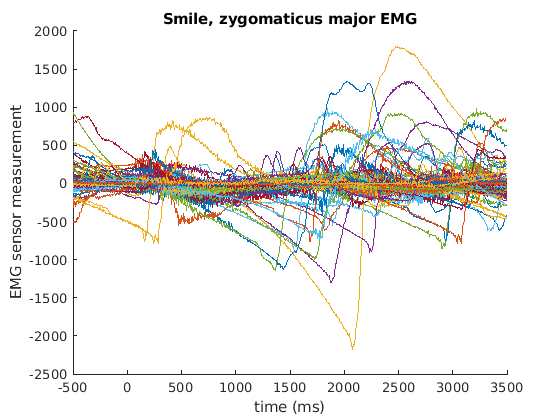

for i = 1:size(smile_ch1, 2)
    plot(time_ms, smile_ch1(:, i))
end
title("Smile, zygomaticus major EMG")
xlabel("time (ms)")
ylabel("EMG sensor measurement")
hold off

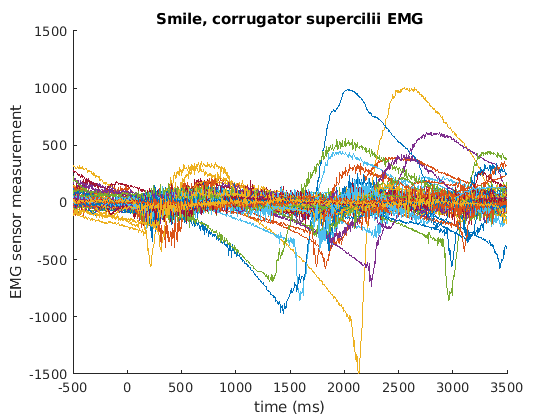


% plot smile, channel 2
figure()
hold on
for i = 1:size(smile_ch2, 2)
    plot(time_ms, smile_ch2(:, i))
end
title("Smile, corrugator supercilii EMG")
xlabel("time (ms)")
ylabel("EMG sensor measurement")
hold off

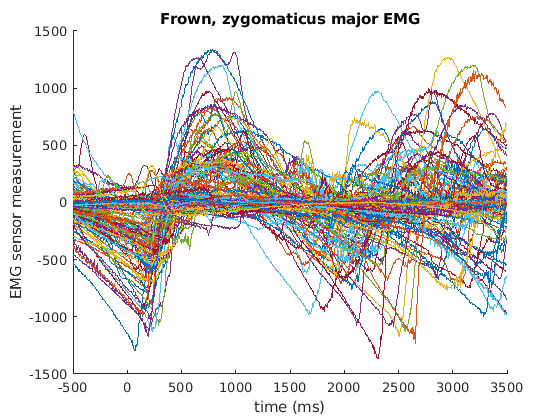


% plot frown, channel 1
figure()
hold on
for i = 1:size(frown_ch1, 2)
    plot(time_ms, frown_ch1(:, i))
end
title("Frown, zygomaticus major EMG")
xlabel("time (ms)")
ylabel("EMG sensor measurement")
hold off

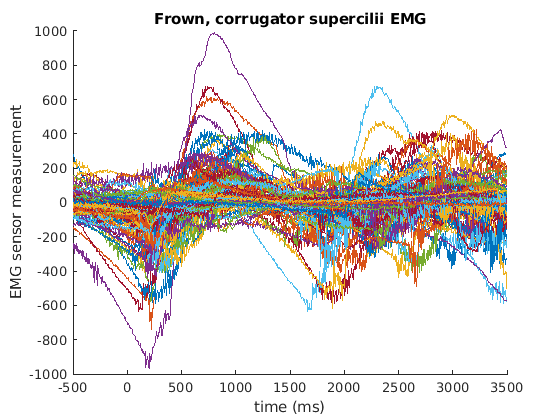


% plot frown, channel 2
figure()
hold on
for i = 1:size(frown_ch2, 2)
    plot(time_ms, frown_ch2(:, i))
end
title("Frown, corrugator supercilii EMG")
xlabel("time (ms)")
ylabel("EMG sensor measurement")
hold off

**Observations**: the smiling pattern and frown pattern look different! The smile pattern has a peak at 2000 ms, whereas the frown pattern has a major peak at 500 ms. The smile pattern seems to have only one distict peak and fall, but the frown pattern seems to have two. The smile patterns seems to have comparatively EMG smaller measurements on average.

#### Exercise 2: Calculate the mean time series (values over time) for the two conditions by showing them on the same plot with time in ms on the x-axis. Do this separately for each channel. What do you observe?

Optional challenge: Include separate lines to indicate 95% confidence intervals around each time course.

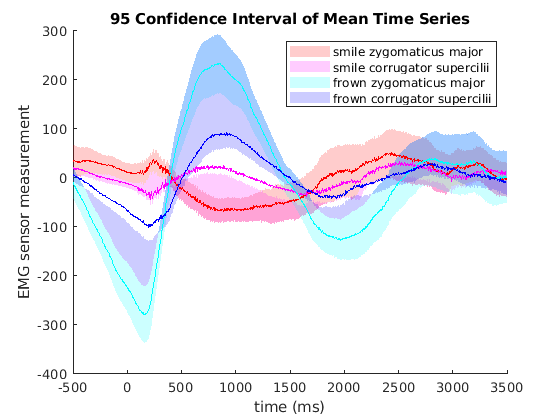

% for 95% confidence interval: x +- z * s/sqrt(n)
z = 1.960;
% for 99.9% confidence interval:
% z = 3.291;

sqn = sqrt(size(smile_ch1, 2)); % from number of trials (same for each condition)

% smile ch1
smile_ch1_mean_over_time = mean(smile_ch1, 2);
smile_ch1_bound = std(smile_ch1, 0, 2) .* z ./ sqn;
smile_ch1_95_CI = [smile_ch1_mean_over_time+smile_ch1_bound, smile_ch1_mean_over_time-smile_ch1_bound];
% smile c2
smile_ch2_mean_over_time = mean(smile_ch2, 2);
smile_ch2_bound = std(smile_ch2, 0, 2) .* z ./ sqn;
smile_ch2_95_CI = [smile_ch2_mean_over_time-smile_ch2_bound, smile_ch2_mean_over_time+smile_ch2_bound];

% frown ch1
frown_ch1_mean_over_time = mean(frown_ch1, 2);
frown_ch1_bound = std(frown_ch1, 0, 2) .* z ./ sqn;
frown_ch1_95_CI = [frown_ch1_mean_over_time-frown_ch1_bound, frown_ch1_mean_over_time+frown_ch1_bound];

% frown ch2
frown_ch2_mean_over_time = mean(frown_ch2, 2);
frown_ch2_bound = std(frown_ch2, 0, 2) .* z ./ sqn;
frown_ch2_95_CI = [frown_ch2_mean_over_time-frown_ch2_bound, frown_ch2_mean_over_time+frown_ch2_bound];

% plotting
xconf_fill = [time_ms fliplr(time_ms)];
smile_ch1_yconf_for_fill = [smile_ch1_95_CI(:,1)' flipud(smile_ch1_95_CI(:, 2))'];
smile_ch2_yconf_for_fill = [smile_ch2_95_CI(:,1)' flipud(smile_ch1_95_CI(:, 2))'];
frown_ch1_yconf_for_fill = [frown_ch1_95_CI(:,1)' flipud(frown_ch1_95_CI(:, 2))'];
frown_ch2_yconf_for_fill = [frown_ch2_95_CI(:,1)' flipud(frown_ch1_95_CI(:, 2))'];

figure()
hold on
fill(xconf_fill, smile_ch1_yconf_for_fill, 'r','FaceAlpha',0.2, 'EdgeColor',"none");
fill(xconf_fill, smile_ch2_yconf_for_fill, 'm','FaceAlpha',0.2, 'EdgeColor',"none");
fill(xconf_fill, frown_ch1_yconf_for_fill, 'c','FaceAlpha',0.2, 'EdgeColor',"none");
fill(xconf_fill, frown_ch2_yconf_for_fill, 'b','FaceAlpha',0.2, 'EdgeColor',"none");
plot(time_ms, smile_ch1_mean_over_time, 'r')
plot(time_ms, smile_ch2_mean_over_time, 'm')
plot(time_ms, frown_ch1_mean_over_time, 'c')
plot(time_ms, frown_ch2_mean_over_time, 'b')
title("95 Confidence Interval of Mean Time Series")
xlabel("time (ms)")
ylabel("EMG sensor measurement")
legend("smile zygomaticus major", "smile corrugator supercilii", "frown zygomaticus major", "frown corrugator supercilii")
hold off

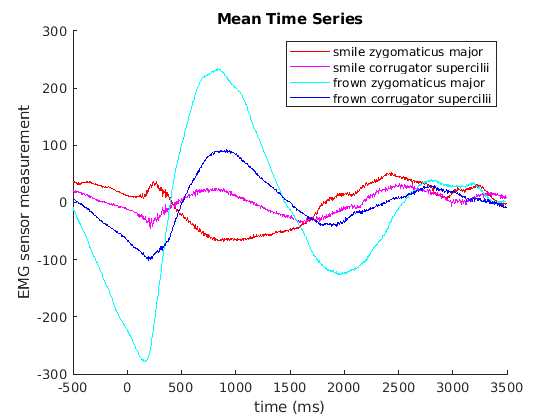

figure()
hold on
plot(time_ms, smile_ch1_mean_over_time, 'r')
plot(time_ms, smile_ch2_mean_over_time, 'm')
plot(time_ms, frown_ch1_mean_over_time, 'c')
plot(time_ms, frown_ch2_mean_over_time, 'b')
title("Mean Time Series")
xlabel("time (ms)")
ylabel("EMG sensor measurement")
legend("smile zygomaticus major", "smile corrugator supercilii", "frown zygomaticus major", "frown corrugator supercilii")
hold off

**Observations:** In both channels, the mean and 95% range is smaller for smile, compared to frown. From 700ms to 1000ms, the 95% confidence intervals for smile and frown do not overlap.

## Thinking about classification of time series data

Our goal is to classify whether a hilarious person is smiling or frowning, based on the EMG data from the two sensors. This builds on the previous machine learning assignments, but now we are starting with data that is a bunch of values over time. In order to get interesting features for our classifier, we want to do some calculations to pull out what might be informative in this data, instead of plugging in all of the raw data. 

#### Exercise 3: For the classification methods that we've looked at so far, why would just plugging in all of the raw data as features not be a great plan?

*There is a lot of overlap between the time series points. Additionally, not every time series point is import for classification distinction, and might confuse the algorithm. There is a lot of raw features, but statistical ML performs better on fewer informative features.*

There are other machine learning methods that are appropriate for taking raw time series data in as inputs. We won't cover them in the main portion of this course, but if you are already feeling confident in machine learning, you might enjoy challenging yourself by investigating these methods. 

Instead of putting in 1000 x 2 EMG time points into our classifier for each trial, we need to find a way to extract and select appropriate features for our analysis. For example, we might want to look at the maximum value in our signal during the time period (epoch/trial) of interest. I can use the max() function to find the maximum value of the signal for each channel and trial, and store this in the array maxvaluesperchantrial

maxvaluesperchantrial = max(traindata,[],2);
size(maxvaluesperchantrial)

ans =      2     1   216


Notice that this has a singleton dimension, so I'll need to use the squeeze function to remove this. I am going to store my potential featurs in a table called trainfeatures to keep things organized. Notice the dimensions of this table and that I labeled the feature variables so that I can keep track of them. 

trainfeatures = array2table(squeeze(maxvaluesperchantrial)','VariableNames',{'Ch1_max','Ch2_max'});

#### Exercise 4: Make a scatter plot that shows the maximum value for each channel with colors representing the two facial expressions. Describe what you observe and explain how well you think these two feature would be able to classify faces vs houses.

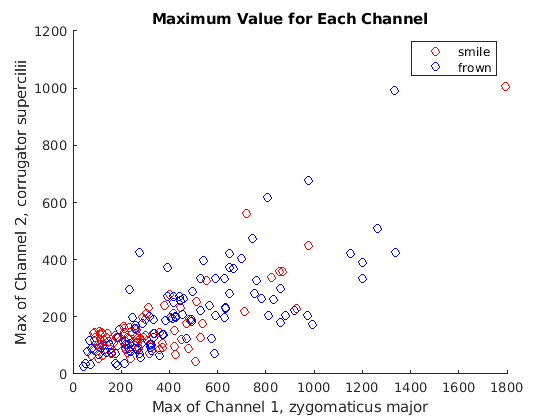

figure
x_axis = 1:size(trainfeatures, 1);
hold on
plot(trainfeatures.Ch1_max(trainlabels == "S pressed"), trainfeatures.Ch2_max(trainlabels == "S pressed"), 'ro')
plot(trainfeatures.Ch1_max(trainlabels == "F pressed"), trainfeatures.Ch2_max(trainlabels == "F pressed"), 'bo')
xlabel("Max of Channel 1, zygomaticus major")
ylabel("Max of Channel 2, corrugator supercilii")
legend("smile", "frown")
title("Maximum Value for Each Channel")
hold off

**Observations: **

Red denotes smiling trials, blue denotes frowning trials.

When using the max of channel 1 and channel 2 are features, the frowning trials are somewhat separated from the smiling trials but there is a decent amount of overlap. The frowning trials tend to have higher max of trial features, but not consistently.

## Quick classification using code

Now we can run a quick support vector machine classification in code.  (If you are using an older version of Matlab, you may need to convert the labels to a table.)

% This is the code that sets up the SVM classifier
trainedClassifier = fitcsvm(trainfeatures, ...
    trainlabels, ...
    'KernelFunction', 'Linear', ...
    'Standardize',false...  
     );  %

The next part sets up cross-validation. Look this up (this is commonly used in machine learning).

% k-fold cross validation
kval = 5; %Choose number of folds. You can also just set this manually.
cpart = cvpartition(trainlabels,'KFold',kval); % k-fold stratified cross validation
partitionedModel = crossval(trainedClassifier,'CVPartition',cpart);

% Make predictions of the crossfold validation predicted based on the traindata
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);
     
% Cross validation output
validationAccuracy = sum(validationPredictions==trainlabels)./length(trainlabels);
%validationAccuracy = 1 - kfoldLoss(partitionedModel); %This is another way
%to find the accuracy. If you want a challenge, you can look up loss
%functions in machine learning

fprintf('\nValidation accuracy = %.2f%%\n', validationAccuracy*100);


Validation accuracy = 53.24%


Okay, so that's probably not an amazing classification accuracy. I think we can do better. The rest of the analysis portion of your assignment to improve upon this (don't forget that there's one more part in the main assignment too).

#### Exercise 5 (more of a full workout): Improve this classifier and share your best method and results here: [https://docs.google.com/spreadsheets/d/18qglL0x-WDohqSMgy8-dADwvpIT5083NRGIYw_Zt__U/edit?usp=sharing](https://docs.google.com/spreadsheets/d/18qglL0x-WDohqSMgy8-dADwvpIT5083NRGIYw_Zt__U/edit?usp=sharing)   (You are welcome to share more than one).

This is a big task, so please read below for some tips about how to approach this.

## Gati's Data Exploration

First plotting by channel

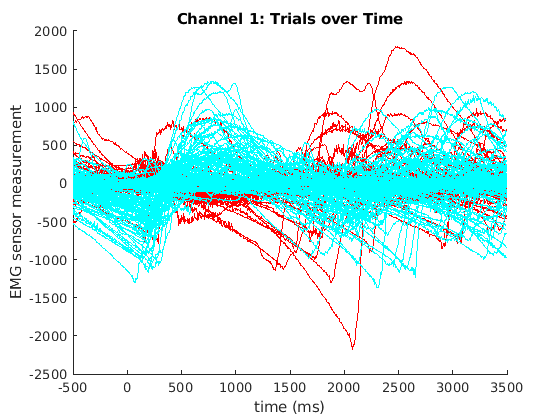

% plot smile, channel 1
figure()
hold on
for i = 1:size(smile_ch1, 2)
    plot(time_ms, smile_ch1(:, i), 'r-')
end
% plot frown, channel 1
for i = 1:size(frown_ch1, 2)
    plot(time_ms, frown_ch1(:, i), 'c-')
end
xlabel("time (ms)")
ylabel("EMG sensor measurement")
title("Channel 1: Trials over Time")
hold off

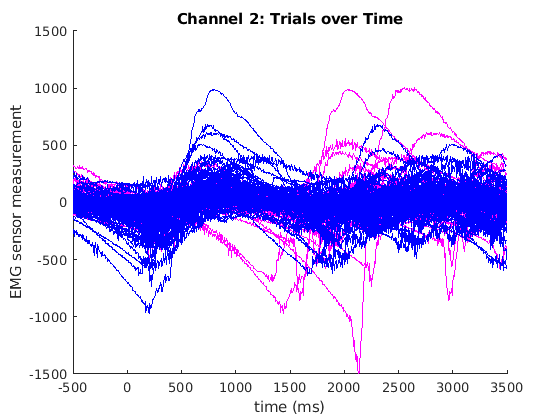

figure()
hold on
% plot smile, channel 2
for i = 1:size(smile_ch2, 2)
    plot(time_ms, smile_ch2(:, i), 'm-')
end
% plot frown, channel 2
for i = 1:size(frown_ch2, 2)
    plot(time_ms, frown_ch2(:, i), 'b-')
end
xlabel("time (ms)")
ylabel("EMG sensor measurement")
title("Channel 2: Trials over Time")
hold off

**Observation:** Looking at these plots, especially for channel 2, I might be able to differentiate smile and frown by making phase-shift a feature. 

Next, I wanted to investigate the skew around the each point time.

The 95% confidence intervals from earlier assume a normal distribution around the mean. I wanted to see where the mean fell in relation to the actual min and max of the range.

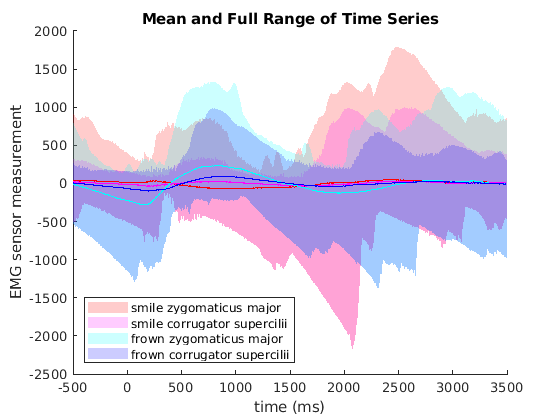


% smile ch1
smile_ch1_mean_over_time = mean(smile_ch1, 2);
smile_ch1_median_over_time = median(smile_ch1, 2);
smile_ch1_range = [max(smile_ch1, [], 2), min(smile_ch1, [], 2)];

% smile c2
smile_ch2_mean_over_time = mean(smile_ch2, 2);
smile_ch2_median_over_time = median(smile_ch2, 2);
smile_ch2_range = [max(smile_ch2, [], 2), min(smile_ch2,[], 2)];

% frown ch1
frown_ch1_mean_over_time = mean(frown_ch1, 2);
frown_ch1_median_over_time = median(frown_ch1, 2);
frown_ch1_range = [max(frown_ch1, [], 2), min(frown_ch1, [], 2)];

% frown ch2
frown_ch2_mean_over_time = mean(frown_ch2, 2);
frown_ch2_median_over_time = median(frown_ch2, 2);
frown_ch2_range = [max(frown_ch2, [], 2), min(frown_ch2, [], 2)];

% plotting fills
xconf_fill = [time_ms fliplr(time_ms)];
smile_ch1_yconf_for_fill = [smile_ch1_range(:,1)' flipud(smile_ch1_range(:, 2))'];
smile_ch2_yconf_for_fill = [smile_ch2_range(:,1)' flipud(smile_ch1_range(:, 2))'];
frown_ch1_yconf_for_fill = [frown_ch1_range(:,1)' flipud(frown_ch1_range(:, 2))'];
frown_ch2_yconf_for_fill = [frown_ch2_range(:,1)' flipud(frown_ch1_range(:, 2))'];

figure()
hold on
fill(xconf_fill, smile_ch1_yconf_for_fill, 'r','FaceAlpha',0.2,'EdgeColor',"none");
fill(xconf_fill, smile_ch2_yconf_for_fill, 'm','FaceAlpha',0.2,'EdgeColor',"none");
fill(xconf_fill, frown_ch1_yconf_for_fill, 'c','FaceAlpha',0.2,'EdgeColor',"none");
fill(xconf_fill, frown_ch2_yconf_for_fill, 'b','FaceAlpha',0.2,'EdgeColor',"none");
plot(time_ms, smile_ch1_mean_over_time, 'r')
plot(time_ms, smile_ch2_mean_over_time, 'm')
plot(time_ms, frown_ch1_mean_over_time, 'c')
plot(time_ms, frown_ch2_mean_over_time, 'b')
title("Mean and Full Range of Time Series")
xlabel("time (ms)")
ylabel("EMG sensor measurement")
legend("smile zygomaticus major", "smile corrugator supercilii", "frown zygomaticus major", "frown corrugator supercilii", "Location", "southwest")
hold off

The previous graph is a little difficult to read, so I simplify the color scheme and further separate the graphed components to more clearly see the overlap between smile and frown.

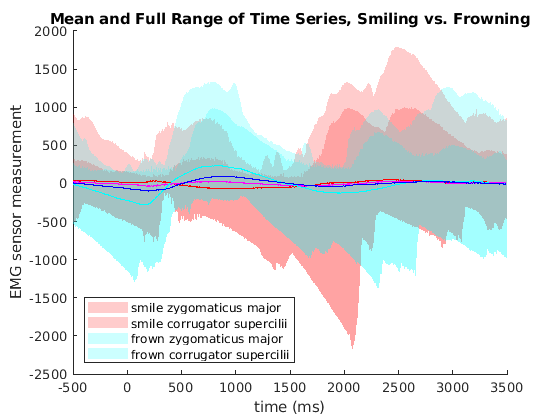

figure()
hold on
fill(xconf_fill, smile_ch1_yconf_for_fill, 'r','FaceAlpha',0.2,'EdgeColor',"none");
fill(xconf_fill, smile_ch2_yconf_for_fill, 'r','FaceAlpha',0.2,'EdgeColor',"none");
fill(xconf_fill, frown_ch1_yconf_for_fill, 'c','FaceAlpha',0.2,'EdgeColor',"none");
fill(xconf_fill, frown_ch2_yconf_for_fill, 'c','FaceAlpha',0.2,'EdgeColor',"none");
plot(time_ms, smile_ch1_mean_over_time, 'r')
plot(time_ms, smile_ch2_mean_over_time, 'm')
plot(time_ms, frown_ch1_mean_over_time, 'c')
plot(time_ms, frown_ch2_mean_over_time, 'b')
title("Mean and Full Range of Time Series, Smiling vs. Frowning")
xlabel("time (ms)")
ylabel("EMG sensor measurement")
legend("smile zygomaticus major", "smile corrugator supercilii", "frown zygomaticus major", "frown corrugator supercilii", "Location", "southwest")
hold off

For highly skewed data (like this data set) median is a better average summary statistic.

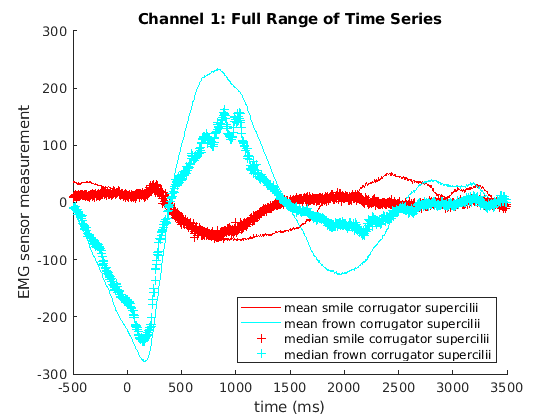

figure()
hold on
plot(time_ms, smile_ch1_mean_over_time, 'r')
plot(time_ms, frown_ch1_mean_over_time, 'c')
plot(time_ms, smile_ch1_median_over_time, 'r+')
plot(time_ms, frown_ch1_median_over_time, 'c+')
title("Channel 1: Full Range of Time Series")
xlabel("time (ms)")
ylabel("EMG sensor measurement")
legend("mean smile corrugator supercilii", "mean frown corrugator supercilii", "median smile corrugator supercilii", "median frown corrugator supercilii", "Location", "southeast")
hold off

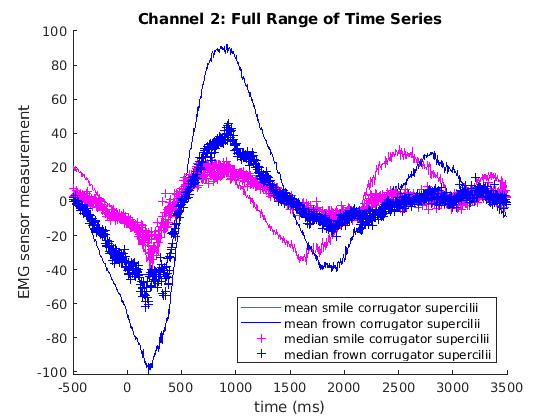

figure()
hold on
plot(time_ms, smile_ch2_mean_over_time, 'm')
plot(time_ms, frown_ch2_mean_over_time, 'b')
plot(time_ms, smile_ch2_median_over_time, 'm+')
plot(time_ms, frown_ch2_median_over_time, 'b+')
title("Channel 2: Full Range of Time Series")
xlabel("time (ms)")
ylabel("EMG sensor measurement")
legend("mean smile corrugator supercilii", "mean frown corrugator supercilii", "median smile corrugator supercilii", "median frown corrugator supercilii", "Location", "southeast")
hold off

**Observation: **Channel 1 is still separated when using median, channel 2 is not well separated by median.

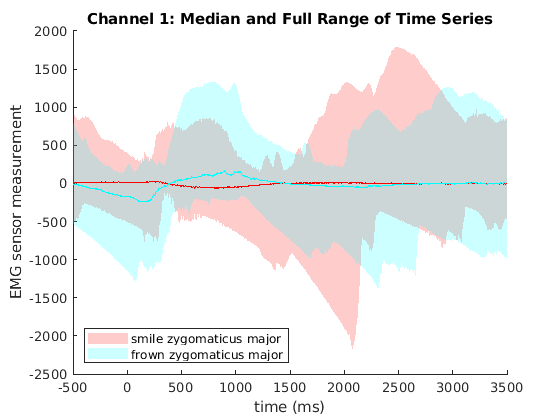

figure()
hold on
fill(xconf_fill, smile_ch1_yconf_for_fill, 'r','FaceAlpha',0.2,'EdgeColor',"none");
fill(xconf_fill, frown_ch1_yconf_for_fill, 'c','FaceAlpha',0.2,'EdgeColor',"none");
plot(time_ms, smile_ch1_median_over_time, 'r')
plot(time_ms, frown_ch1_median_over_time, 'c')
title("Channel 1: Median and Full Range of Time Series")
xlabel("time (ms)")
ylabel("EMG sensor measurement")
legend("smile zygomaticus major", "frown zygomaticus major", "Location", "southwest")
hold off

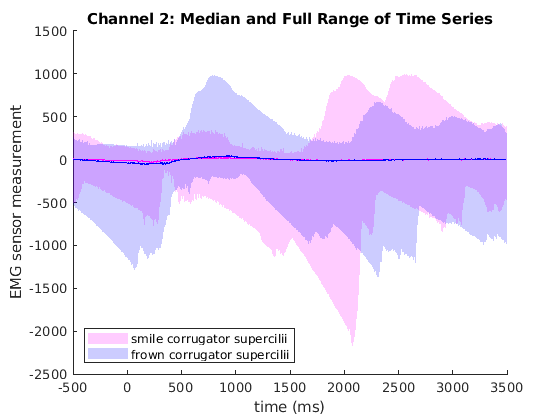

figure()
hold on
fill(xconf_fill, smile_ch2_yconf_for_fill, 'm','FaceAlpha',0.2,'EdgeColor',"none");
fill(xconf_fill, frown_ch2_yconf_for_fill, 'b','FaceAlpha',0.2,'EdgeColor',"none");
plot(time_ms, smile_ch2_median_over_time, 'm')
plot(time_ms, frown_ch2_median_over_time, 'b')
title("Channel 2: Median and Full Range of Time Series")
xlabel("time (ms)")
ylabel("EMG sensor measurement")
legend("smile corrugator supercilii", "frown corrugator supercilii", "Location", "southwest")
hold off

**Observation: **There is no absolute range that 100% separates smile and frown cleanly. Furthermore, the median (average) value of the time series are very close to the center with very little overall oscillation.

I am looking for a feature set that somewhat cleanly splits smile and frown trials.

idx_0ms = 126;
idx_500ms = 251;
idx_1000ms = 376;

pre_range = 1:idx_0ms;
range1 = idx_0ms:idx_500ms;
range2 = idx_500ms:idx_1000ms;

% remove the average signal from each trial (center each trial around zero).
train_data_pre_mean = mean(traindata(:, pre_range, :), 2);
train_data_range1_norm_by_pre_mean = mean(traindata(:, range1, :), 2) - train_data_pre_mean;
train_data_range2_norm_by_pre_mean = mean(traindata(:, range2, :), 2) - train_data_pre_mean;

trainfeatures_prerange = array2table(squeeze(train_data_pre_mean)','VariableNames',{'Ch1','Ch2'});
trainfeatures_range1_norm_by_pre_mean = array2table(squeeze(train_data_range1_norm_by_pre_mean)','VariableNames',{'Ch1','Ch2'});
trainfeatures_range2_norm_by_pre_mean = array2table(squeeze(train_data_range2_norm_by_pre_mean)','VariableNames',{'Ch1','Ch2'});

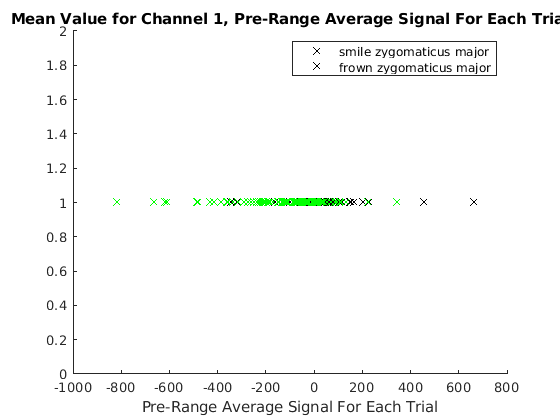

figure
hold on
plot(trainfeatures_prerange.Ch1(trainlabels == "S pressed"), ones(sum(trainlabels == "S pressed")), 'kx')
plot(trainfeatures_prerange.Ch1(trainlabels == "F pressed"), ones(sum(trainlabels == "F pressed")), 'gx')
legend("smile zygomaticus major", "frown zygomaticus major")
xlabel("Pre-Range Average Signal For Each Trial")
title("Mean Value for Channel 1, Pre-Range Average Signal For Each Trial")
hold off

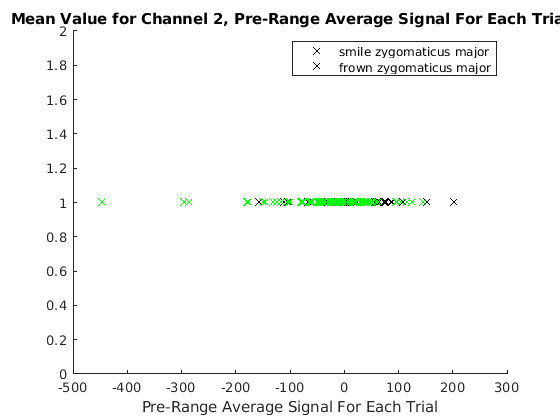

figure
hold on
plot(trainfeatures_prerange.Ch2(trainlabels == "S pressed"), ones(sum(trainlabels == "S pressed")), 'kx')
plot(trainfeatures_prerange.Ch2(trainlabels == "F pressed"), ones(sum(trainlabels == "F pressed")), 'gx')
legend("smile zygomaticus major", "frown zygomaticus major")
xlabel("Pre-Range Average Signal For Each Trial")
title("Mean Value for Channel 2, Pre-Range Average Signal For Each Trial")
hold off

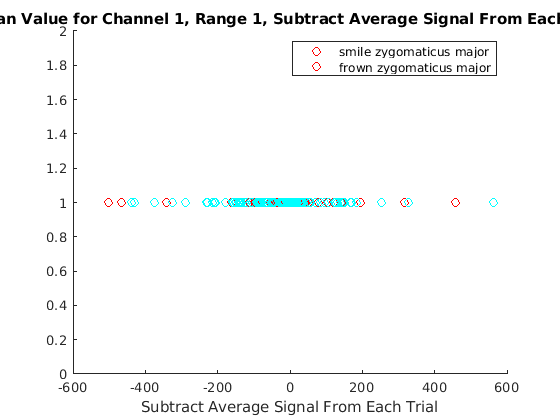

figure
hold on
plot(trainfeatures_range1_norm_by_pre_mean.Ch1(trainlabels == "S pressed"), ones(sum(trainlabels == "S pressed")), 'ro')
plot(trainfeatures_range1_norm_by_pre_mean.Ch1(trainlabels == "F pressed"), ones(sum(trainlabels == "F pressed")), 'co')
legend("smile zygomaticus major", "frown zygomaticus major")
xlabel("Subtract Average Signal From Each Trial")
title("Mean Value for Channel 1, Range 1, Subtract Average Signal From Each Trial")
hold off

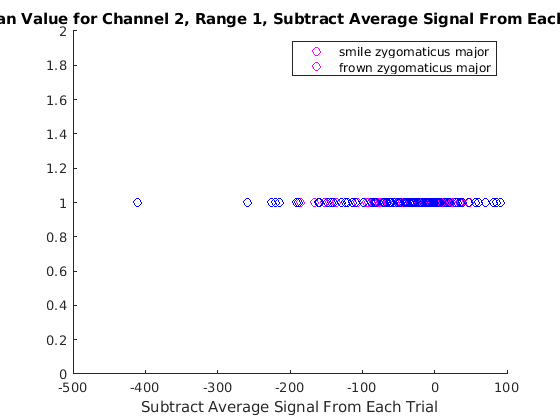


figure
hold on
plot(trainfeatures_range1_norm_by_pre_mean.Ch2(trainlabels == "S pressed"), ones(sum(trainlabels == "S pressed")), 'mo')
plot(trainfeatures_range1_norm_by_pre_mean.Ch2(trainlabels == "F pressed"), ones(sum(trainlabels == "F pressed")), 'bo')
legend("smile zygomaticus major", "frown zygomaticus major")
xlabel("Subtract Average Signal From Each Trial")
title("Mean Value for Channel 2, Range 1, Subtract Average Signal From Each Trial")
hold off

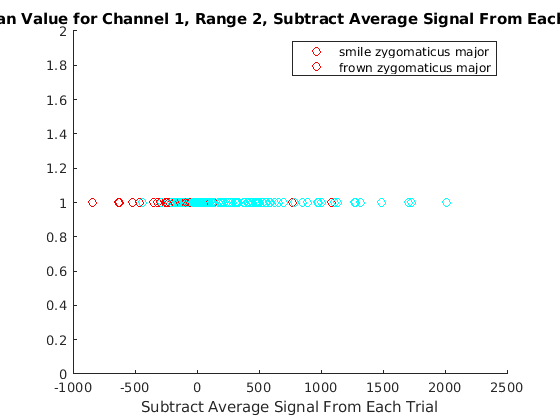


figure
hold on
plot(trainfeatures_range2_norm_by_pre_mean.Ch1(trainlabels == "S pressed"), ones(sum(trainlabels == "S pressed")), 'ro')
plot(trainfeatures_range2_norm_by_pre_mean.Ch1(trainlabels == "F pressed"), ones(sum(trainlabels == "F pressed")), 'co')
legend("smile zygomaticus major", "frown zygomaticus major")
xlabel("Subtract Average Signal From Each Trial")
title("Mean Value for Channel 1, Range 2, Subtract Average Signal From Each Trial")
hold off

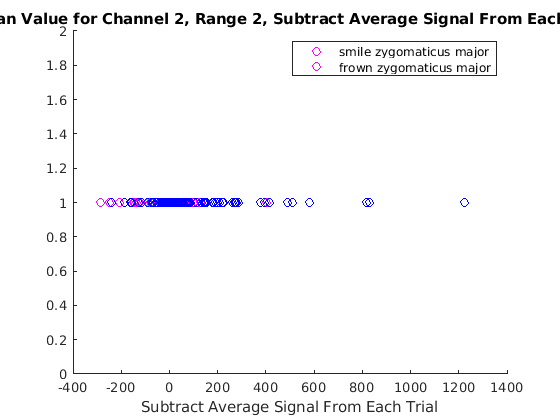

figure
hold on
plot(trainfeatures_range2_norm_by_pre_mean.Ch2(trainlabels == "S pressed"), ones(sum(trainlabels == "S pressed")), 'mo')
plot(trainfeatures_range2_norm_by_pre_mean.Ch2(trainlabels == "F pressed"), ones(sum(trainlabels == "F pressed")), 'bo')
legend("smile zygomaticus major", "frown zygomaticus major")
xlabel("Subtract Average Signal From Each Trial")
title("Mean Value for Channel 2, Range 2, Subtract Average Signal From Each Trial")
hold off

None of these features separate out smile and frown particularly well.

## Calculating Other Features

Since none of my previous features separated smile and frown, I will try these other features.

- root mean square (rms)

- mean of the absolute value of the signal

- the variance of the signal

Root Mean Square of the Signal

train_data_rms = sqrt(sum(traindata.^2, 2) / (size(traindata, 2)+1));

train_data_rms = 2×1×216 single array
train_data_rms(:,:,1) =

  121.1184
   33.1003


train_data_rms(:,:,2) =

  268.4055
  152.3011


train_data_rms(:,:,3) =

   58.2349
   25.1112


train_data_rms(:,:,4) =

  945.4973
  518.2565


train_data_rms(:,:,5) =

  402.6478
  297.2873


train_data_rms(:,:,6) =

  401.9562
  300.9240


train_data_rms(:,:,7) =

   79.2063
   58.1980


train_data_rms(:,:,8) =

   49.3519
   29.8974


train_data_rms(:,:,9) =

   71.1099
   34.6965


train_data_rms(:,:,10) =

  182.9380
   55.8389


train_data_rms(:,:,11) =

   48.8181
   32.6765


train_data_rms(:,:,12) =

  160.6356
  128.9845


train_data_rms(:,:,13) =

  258.8968
  211.0543


train_data_rms(:,:,14) =

  257.5093
  210.6692


train_data_rms(:,:,15) =

  501.9197
  328.9387


train_data_rms(:,:,16) =

  562.1268
  370.6764


train_data_rms(:,:,17) =

  456.1308
  270.7810


train_data_rms(:,:,18) =

  403.7381
  204.7319


train_data_rms(:,:,19) =

  316.2811
  169.2954


train_data_rms(:,:,20

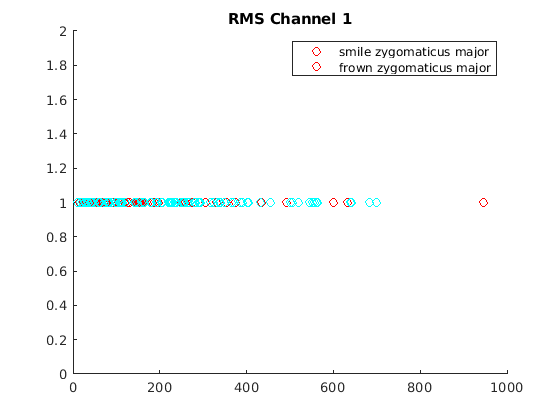

train_data_rms_t = array2table(squeeze(train_data_rms)','VariableNames',{'Ch1','Ch2'});
figure
hold on
plot(train_data_rms_t.Ch1(trainlabels == "S pressed"), ones(sum(trainlabels == "S pressed")), 'ro')
plot(train_data_rms_t.Ch1(trainlabels == "F pressed"), ones(sum(trainlabels == "F pressed")), 'co')
legend("smile zygomaticus major", "frown zygomaticus major")
title("RMS Channel 1")
hold off

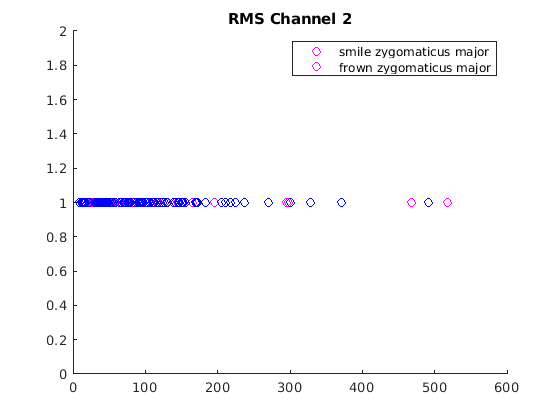

figure
hold on
plot(train_data_rms_t.Ch2(trainlabels == "S pressed"), ones(sum(trainlabels == "S pressed")), 'mo')
plot(train_data_rms_t.Ch2(trainlabels == "F pressed"), ones(sum(trainlabels == "F pressed")), 'bo')
legend("smile zygomaticus major", "frown zygomaticus major")
title("RMS Channel 2")
hold off

Mean of Absolute Value of the Signal

train_data_mav = mean(abs(traindata), 2);

train_data_mav = 2×1×216 single array
train_data_mav(:,:,1) =

   65.0934
   22.9996


train_data_mav(:,:,2) =

  171.4914
  112.1676


train_data_mav(:,:,3) =

   43.0836
   19.5644


train_data_mav(:,:,4) =

  692.2145
  359.3473


train_data_mav(:,:,5) =

  315.6429
  209.0325


train_data_mav(:,:,6) =

  305.6711
  225.8033


train_data_mav(:,:,7) =

   57.4484
   43.6216


train_data_mav(:,:,8) =

   33.3150
   22.3469


train_data_mav(:,:,9) =

   48.1867
   25.7866


train_data_mav(:,:,10) =

  152.4441
   48.0933


train_data_mav(:,:,11) =

   40.4652
   26.4091


train_data_mav(:,:,12) =

  105.8864
   73.5561


train_data_mav(:,:,13) =

  203.5211
  153.4225


train_data_mav(:,:,14) =

  200.8336
  152.9901


train_data_mav(:,:,15) =

  407.3906
  272.2933


train_data_mav(:,:,16) =

  503.4903
  333.8970


train_data_mav(:,:,17) =

  401.3069
  233.9274


train_data_mav(:,:,18) =

  356.4908
  174.0896


train_data_mav(:,:,19) =

  243.0884
  124.3712


train_data_mav(:,:,20

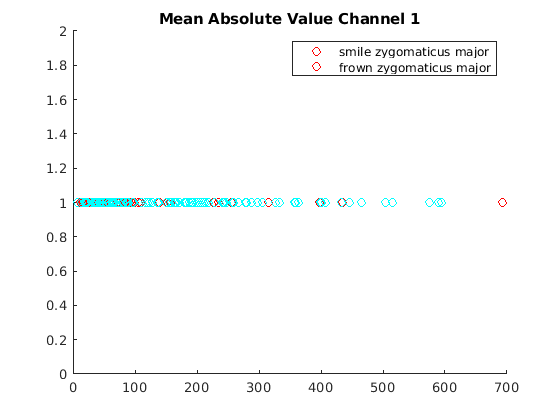

train_data_mav_t = array2table(squeeze(train_data_mav)','VariableNames',{'Ch1','Ch2'});
figure
hold on
plot(train_data_mav_t.Ch1(trainlabels == "S pressed"), ones(sum(trainlabels == "S pressed")), 'ro')
plot(train_data_mav_t.Ch1(trainlabels == "F pressed"), ones(sum(trainlabels == "F pressed")), 'co')
legend("smile zygomaticus major", "frown zygomaticus major")
title("Mean Absolute Value Channel 1")
hold off

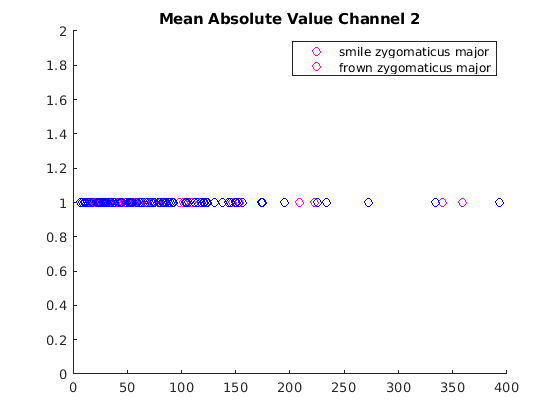


figure
hold on
plot(train_data_mav_t.Ch2(trainlabels == "S pressed"), ones(sum(trainlabels == "S pressed")), 'mo')
plot(train_data_mav_t.Ch2(trainlabels == "F pressed"), ones(sum(trainlabels == "F pressed")), 'bo')
legend("smile zygomaticus major", "frown zygomaticus major")
title("Mean Absolute Value Channel 2")
hold off

Variance of Signal

train_data_var = var(traindata, 0, 2);

train_data_var = 2×1×216 single array
train_data_var(:,:,1) =

   1.0e+04 *

    1.4664
    0.1045


train_data_var(:,:,2) =

   1.0e+04 *

    7.2173
    2.3231


train_data_var(:,:,3) =

   1.0e+03 *

    3.3588
    0.6270


train_data_var(:,:,4) =

   1.0e+05 *

    8.9330
    2.6832


train_data_var(:,:,5) =

   1.0e+05 *

    1.6129
    0.8780


train_data_var(:,:,6) =

   1.0e+05 *

    1.6147
    0.9066


train_data_var(:,:,7) =

   1.0e+03 *

    3.8596
    2.4118


train_data_var(:,:,8) =

   1.0e+03 *

    2.4021
    0.8758


train_data_var(:,:,9) =

   1.0e+03 *

    3.8562
    1.1270


train_data_var(:,:,10) =

   1.0e+04 *

    3.3515
    0.3104


train_data_var(:,:,11) =

   1.0e+03 *

    2.3227
    1.0668


train_data_var(:,:,12) =

   1.0e+04 *

    2.1052
    1.4156


train_data_var(:,:,13) =

   1.0e+04 *

    6.6096
    4.4440


train_data_var(:,:,14) =

   1.0e+04 *

    6.6200
    4.4444


train_data_var(:,:,15) =

   1.0e+05 *

    2.4517
    1.0690


train_data_

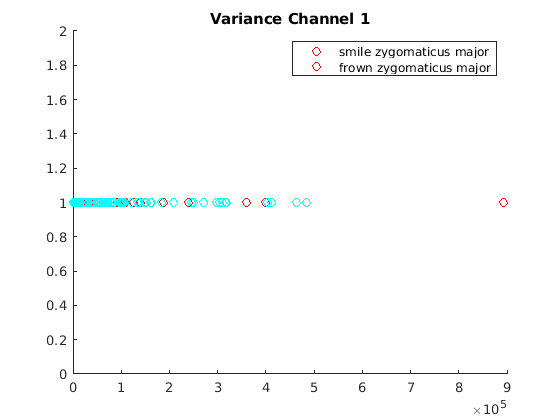

train_data_var_t = array2table(squeeze(train_data_var)','VariableNames',{'Ch1','Ch2'});
figure
hold on
plot(train_data_var_t.Ch1(trainlabels == "S pressed"), ones(sum(trainlabels == "S pressed")), 'ro')
plot(train_data_var_t.Ch1(trainlabels == "F pressed"), ones(sum(trainlabels == "F pressed")), 'co')
legend("smile zygomaticus major", "frown zygomaticus major")
title("Variance Channel 1")
hold off

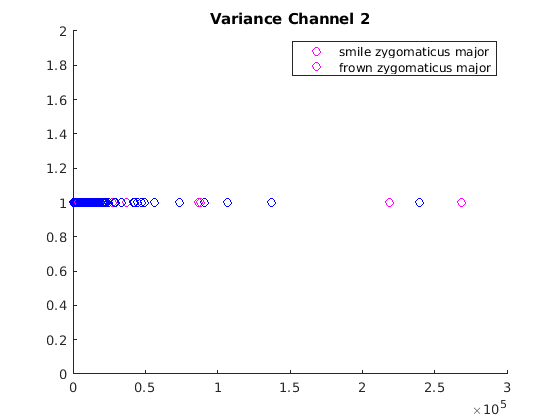


figure
hold on
plot(train_data_var_t.Ch2(trainlabels == "S pressed"), ones(sum(trainlabels == "S pressed")), 'mo')
plot(train_data_var_t.Ch2(trainlabels == "F pressed"), ones(sum(trainlabels == "F pressed")), 'bo')
legend("smile zygomaticus major", "frown zygomaticus major")
title("Variance Channel 2")
hold off

Observation: RMS, MAV, and variance do not separate smile and frown classes. All of them bunch up in the smaller values.

## Further Investigation

Since smile and frown values for RMS, MAV, and variance densely overlap in the smaller values, applying a logarithm might separate them out.

Log Root Mean Square of the Signal

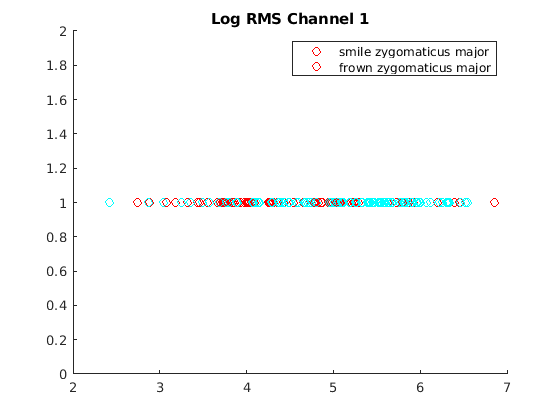

train_data_rms_log = array2table(squeeze(log(train_data_rms))','VariableNames',{'Ch1','Ch2'});
figure
hold on
plot(train_data_rms_log.Ch1(trainlabels == "S pressed"), ones(sum(trainlabels == "S pressed")), 'ro')
plot(train_data_rms_log.Ch1(trainlabels == "F pressed"), ones(sum(trainlabels == "F pressed")), 'co')
legend("smile zygomaticus major", "frown zygomaticus major")
title("Log RMS Channel 1")
hold off

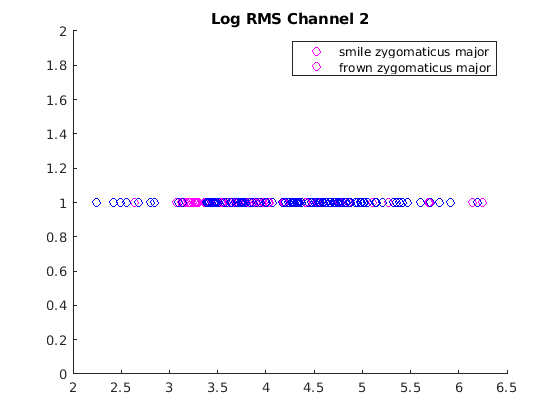

figure
hold on
plot(train_data_rms_log.Ch2(trainlabels == "S pressed"), ones(sum(trainlabels == "S pressed")), 'mo')
plot(train_data_rms_log.Ch2(trainlabels == "F pressed"), ones(sum(trainlabels == "F pressed")), 'bo')
legend("smile zygomaticus major", "frown zygomaticus major")
title("Log RMS Channel 2")
hold off

Log Mean of Absolute Value of the Signal

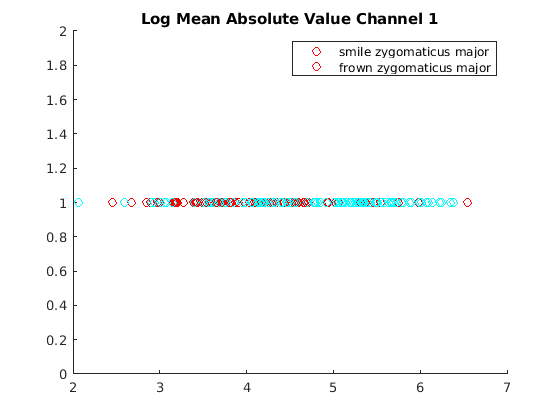

train_data_mav_log = array2table(squeeze(log(train_data_mav))','VariableNames',{'Ch1','Ch2'});
figure
hold on
plot(train_data_mav_log.Ch1(trainlabels == "S pressed"), ones(sum(trainlabels == "S pressed")), 'ro')
plot(train_data_mav_log.Ch1(trainlabels == "F pressed"), ones(sum(trainlabels == "F pressed")), 'co')
legend("smile zygomaticus major", "frown zygomaticus major")
title("Log Mean Absolute Value Channel 1")
hold off

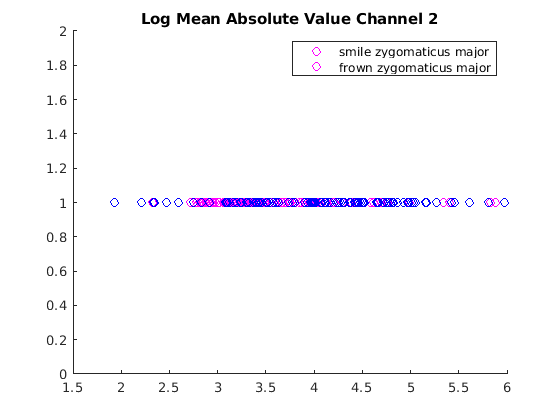


figure
hold on
plot(train_data_mav_log.Ch2(trainlabels == "S pressed"), ones(sum(trainlabels == "S pressed")), 'mo')
plot(train_data_mav_log.Ch2(trainlabels == "F pressed"), ones(sum(trainlabels == "F pressed")), 'bo')
legend("smile zygomaticus major", "frown zygomaticus major")
title("Log Mean Absolute Value Channel 2")
hold off

Log Variance of Signal

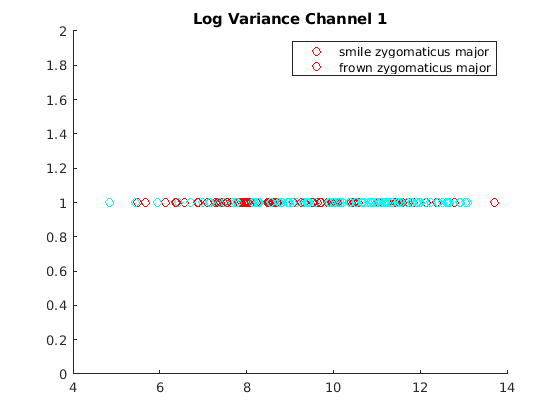

train_data_var_log = array2table(squeeze(log(train_data_var))','VariableNames',{'Ch1','Ch2'});
figure
hold on
plot(train_data_var_log.Ch1(trainlabels == "S pressed"), ones(sum(trainlabels == "S pressed")), 'ro')
plot(train_data_var_log.Ch1(trainlabels == "F pressed"), ones(sum(trainlabels == "F pressed")), 'co')
legend("smile zygomaticus major", "frown zygomaticus major")
title("Log Variance Channel 1")
hold off

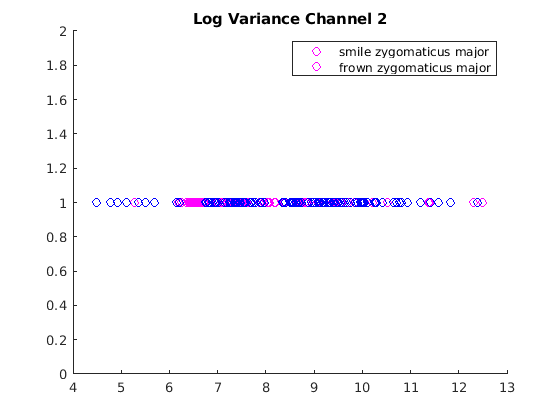


figure
hold on
plot(train_data_var_log.Ch2(trainlabels == "S pressed"), ones(sum(trainlabels == "S pressed")), 'mo')
plot(train_data_var_log.Ch2(trainlabels == "F pressed"), ones(sum(trainlabels == "F pressed")), 'bo')
legend("smile zygomaticus major", "frown zygomaticus major")
title("Log Variance Channel 2")
hold off

Observation: these log transformed features somewhat separate frown and smile.

#### Default SVM Classification on Feature Set:

                Features                        Accuracy           Smile_TPR          Frown _TPR                

- train_data_rms_log         0.6620               0.6574                 0.6667

- train_data_mav_log        0.6574               0.6759                 0.6389

- train_data_var_log          0.6620                0.6667                0.6574

- all log features                0.6991                0.7593                 0.6389          

log_fs = [ renamevars(train_data_rms_log, ["Ch1", "Ch2"], ["RMS1", "RMS2"]) renamevars(train_data_mav_log, ["Ch1", "Ch2"], ["MAV1", "MAV2"]) renamevars(train_data_var_log, ["Ch1", "Ch2"], ["VAR1", "VAR2"]) ];

% This is the code that sets up the SVM classifier
trainedClassifier = fitcsvm(log_fs, ...
    trainlabels, ...
    'KernelFunction', 'Linear', ...
    'Standardize',false...  
     );

The next part sets up cross-validation. Look this up (this is commonly used in machine learning).

% k-fold cross validation
kval = 5; %Choose number of folds. You can also just set this manually.
cpart = cvpartition(trainlabels,'KFold',kval); % k-fold stratified cross validation
partitionedModel = crossval(trainedClassifier,'CVPartition',cpart);

% Make predictions of the crossfold validation predicted based on the traindata
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);
     
% Cross validation output
validationAccuracy = sum(validationPredictions==trainlabels)./length(trainlabels);
%validationAccuracy = 1 - kfoldLoss(partitionedModel); %This is another way
%to find the accuracy. If you want a challenge, you can look up loss
%functions in machine learning
fprintf('\nValidation accuracy = %.2f%%\n', validationAccuracy*100);


Validation accuracy = 68.52%


smile_tpr = sum(trainlabels=="S pressed" & validationPredictions==trainlabels)/sum(trainlabels=="S pressed")

smile_tpr = 0.7500

frown_tpr = sum(trainlabels=="F pressed" & validationPredictions==trainlabels)/sum(trainlabels=="F pressed")

frown_tpr = 0.6204

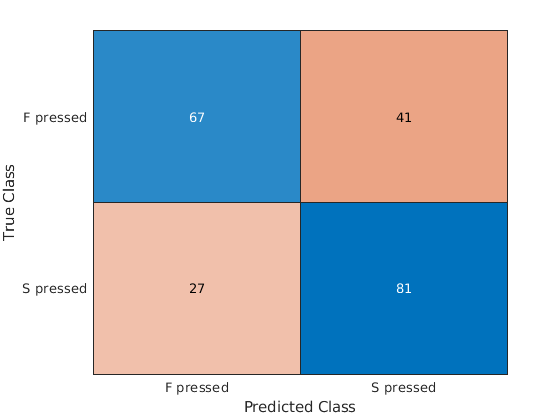

confusionchart(trainlabels,validationPredictions)

## Hot tips for improving the EMG classifier    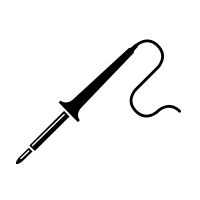

There are several strategies that you might take to improve the classifier:

- Add additional preprocessing

- Narrow the time window

- Calculate additional features

- Try a different algorithm and/or tweak the algorithm parameters.

These are numbered based on the order that you apply them to your data. However, they are essentially in reverse order of importance (calculating more/different features is the most important). See more info about each of these strategies below.

### 1. Add additional preprocessing

These data have already mostly been preprocessed for you using:

- a high pass filter at 0.5 Hz to remove drift

- a notch filter from 56 to 64 Hz to remove electrical noise at 60 Hz (this would be 50 Hz, if I were in Europe)

- epoching to chop the data up into 1000 timepoints or 4 seconds sampled at 250 samples per second (250 Hz sampling rate)

However, there are other preprocessing that is sometimes used for EMG data. I suggest only doing one of these at any given time: 

- remove the average signal from each trial (centering each trial around zero).

- filter the data more to remove noise

- remove the average signal from the baseline (timepoints prior to the facial expression, which happens around 0 ms)

You might enjoy these Matlab functions: mean(), highpass(), lowpass(), bandpass()

### 2. Narrow the time window

Right now, the data include a pretty large time window, include data from before I even started to make the facial expression. You can experiment with different windows. It might be helpful to go back and look at your time series plots from the beginning of this notebook to think about what time window would be appropriate.

 We might choose to use only a subset of this epoch, especially since it might not make sense to extract information from before the event happened (at 0 ms). Here's some code that might be helpful

timewindowforfeatures = [-100 1000]; %start and stop in ms. If timepoints don't line up, this will select a slightly later time
timewindowepochidx = (find(time_ms>=timewindowforfeatures(1),1)):(find(time_ms>=timewindowforfeatures(2),1));
windoweddata = traindata(:,timewindowepochidx,:);
size(traindata)
size(windoweddata)

### 3. Calculate additional features 

Here are some ideas for features to add (you can look these up in online resources, including some papers linked below):

- mean of the absolute value of the signal

- root mean square (rms) 

- the variance of the signal

- integrated EMG (iEMG)

- simple squared integral (SSI)

- bandpower in different frequency bands (e.g., 64 to 110 Hz)

- other ideas that you come up with, you might look back at the plots to think about how the smile and frown signals look different.

***There are also existing Matlab functions for many of these (or parts of them), so you don't need to code the whole formula from scratch.***

Here are a couple papers with some info, but you can also find your own. 

[Mithbavkar, Shraddha Atul, and Milind Shantilal Shah. "Recognition of Emotion Through Facial Expressions Using EMG Signal." 2019 International Conference on Nascent Technologies in Engineering (ICNTE). IEEE, 2019.](https://drive.google.com/file/d/1z2df6YGj-S1I4xbYPOcqUqHkP70LQFSM/view?usp=sharing)

Paper you looked at already in this assignment: [https://www.ncbi.nlm.nih.gov/pmc/articles/PMC1455479/](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC1455479/))

### 4. Try a different algorithm and/or tweak the algorithm parameters.

You can look up the different parameters you can put into the fitcsvm function, these include things like: 'OutlierFraction',0.10,...

Or you might want to look up other classifiers besides SVM to use here. Matlab has lots of options, which have different parameters, but tend to take in the same form of predictors and response variables.

[https://www.mathworks.com/help/stats/classification.html](https://www.mathworks.com/help/stats/classification.html)